# DoA performance evaluation

**Description**: This file evaluates the performance of the SIM to estimate the DoA. The performance is evaluated for a single user, see a diagram representation in Fig. 1a). The performance account for the evaluation of the relative errors in determining the electric angle of arrival $\psi _{\text {x}}$. Due to the symetry of the system model in Fig. 1a), the evaluation of the relative for for the second electric angle of arrival $(\psi _{\text {y}})$ follows the same procedure yielding the same result.

Figure 1: Representation of the SIM array and reference system.

## Relative error evaluation

We account for the performance evaluation with the relative error of the angle as: 

$\mathrm{Relative\ Error}_{\psi _{\text {x}}} =\mathbb{E} \left[\frac{|\bar {\psi }_{\text {x}}- \hat {\psi }_{\text {x},n,t}|}{|\bar {\psi }_{\text {x}}|}\right]$ (1)

where

- $\bar \psi _{\textrm {x}} =\kappa d_{\textrm {x}}\sin \left ({{ \vartheta }}\right)\cos \left ({{ \varphi }}\right)$ is the actual electric angle of the mobile user, and $\bar \psi _{\textrm {x}}\in [-1\ 1]$, see [1, Eq.(1)]

- $\kappa$is the wavenumber, given as

            $\kappa=\frac{2\pi}{\lambda}$ (2)

- $\lambda$ is the wavelength, given as

            $\lambda=\frac{c}{f}$ (3)

- $c$ is the speed of light

- $f$is the center frequency of transmissions.

- $d_x$ is the element spacing in the $x$ axis of the first layer, see Fig. 1b)

- $\vartheta$ is the user elevation angle; see Fig. 1c)

- $\varphi$ is the user azimuth angle; see Fig. 1c)

- $\hat {\psi }_{\text {x},n,t}$ is the estimated angle by the SIM

- $n$ is the atom index, see Fig. 1b)

- $t$ is the time index.

The expected value in Eq. (1) is upper bounded with a similar procedure to [1, Eq.(36)] yielding

$ \textrm {Relative Error}_{\psi _{\text {x}}} \leq \frac{1}{P} \sum _{p=1}^{P}\sum _{n=1}^{N}\sum _{t=1}^{T}\frac{|{{ \bar {\psi }_{\text {x}_p} - \hat {\psi }_{\text {x}_p,n,t}}}|}{|\bar {\psi }_{\text {x}_p}|} \times Q\left ({{ \frac {9h_{n,t}\sqrt [{3}]{\frac {b_{n,t}}{h_{n,t}}}-9h_{n,t}+2}{2} }}\right),  $ (4)

where

- $\text {x}_p$ denotes the index for the angle sequence $\bar{\psi}$

- $Q(\cdot)$ is the Q-error function and evaluates the probability $\Pr \left \{{{ \left |{{ r_{n,t} }}\right |^{2}\geq \left |{{ r_{\breve {n},\breve {t}} }}\right |^{2} }}\right \}$

- $\Pr \left \{{{ \left |{{ r_{n,t} }}\right |^{2}\geq \left |{{ r_{\breve {n},\breve {t}} }}\right |^{2} }}\right \}$ is the probability of observing at the $n$-th probe and the $t$-th time index the highest magnitude in the presence of noise, in comparison to the highest magnitude in the absence of noise as observed at the $\breve{n}$-th probe and $\breve{t}$-th time index.

- $h_{n,t} =\frac{\mu _{2,n,t}^{3}}{\mu _{3,n,t}^{2}}$ (5)

- $b_{n,t}=h_{n,t}-\mu _{1,n,t}\sqrt {\frac {h_{n,t}}{\mu _{2,n,t}}}$ (6)

- $\mu _{i,n,t}=\left ({{ -1 }}\right)^{i}\left ({{ 2+i\left |{{ \sqrt {2\varrho }\tilde {\mathbf{g}}_{\breve {n}}^{H} \mathbf{\Upsilon }_{0,\breve {t}}\mathbf{a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2} }}\right)+2+i\left |{{ \sqrt {2\varrho }\tilde {\mathbf {g}}_{n}^{H} \mathbf{\Upsilon }_{0,t}\mathbf{a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2}$ (7)

- $\varrho$ is the SNR

- The $\breve{n}$-th probe and the $\breve{t}$-th time refer to the antenna and time indexes that reflects the maximum received signal in the abscence of noise. These indexes also refer to the location of the FFT peak.

## **Algorithm **

This algorithm aims to evaluate Eq. (2) and starts from bottom (Eq. (5)) to top (Eq. (3)). 

### Evaluation of Eq. (7)

To evaluate Eq. (7) we need first to determine the index pair $(\breve{n},\breve{t})$, which refers to the antenna probe and the time index of the FFT peak in the absence of noise. In that regard, we need first to develop the 2D-DFT matrix with the SIM and evaluate later the signal received on each different probe. The operation follows (see [1, Eq.(41)])

$\left [{{ \breve {n}_\psi,\breve {t}_\psi }}\right ]=\arg \underset{t_\psi=1,\cdots, T}{\underset {n_\psi=1,\cdots,N,}{\max }} \left |{{ \tilde {\mathbf{g}}_{n_\psi}^{H} \mathbf {\Upsilon }_{0,t_\psi}\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2}$ (8)

**Interpretation of Eq. (8)**

- $\tilde{\mathbf{g}}^H_{n_\psi}\,\in\,\mathbb{C}^{1\times N}$ refers to the $n_\psi$-th column of the 2D-DFT matrix $\mathbf{G}$ and evaluates the amplitude of the Fourier kernel for a given angle $\psi$; see the definition for this matrix below in Eq. (14). 

- $\mathbf {\Upsilon }_{0,t_\psi}$ is the transmission matrix for the input layer and implements a angular shift of the incoming signal with the parameter $t$; see the definition of this matrix below in Eq. (17).

- In this way, the product $\tilde {\mathbf{g}}_{n}^{H} \mathbf {\Upsilon }_{0,t_\psi}$ in relation in (8) realizes a angular shift on the Fourier kernel,  controled with the $t$ parameter. This angular shift allows to evaluate the maximum of the received amplitude more granularly.

- Finally, $\left |{{ \tilde {\mathbf{g}}_{n_\psi}^{H} \mathbf {\Upsilon }_{0,t_\psi}\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2}$ evaluates the power of the wavevector $\mathbf{\kappa}$ with $\psi$.

**Impact of parameters in Eq. (8)**

This equation comprises two parameters $N$ and $T$.

- $N$refers to the number of meta-atoms in the input layer of the SIM and equals to the number of probes as well. This parameter determines the number of bins in the transformed domain $\psi$. The larger this parameter the less the errors.

- $T$ refers to the amount of angular shifts in the transformed domain. The larger the value of $T$, the accurate on the location of the peak.

The definition of the parameters in Eq. (8) follows the description:

- $n_\psi$ refers to the $n_\psi$-th row of the $\mathbf{G}$ matrix, which realizes the 2D-DFT matrix transform; see its definition below in Eq. (14).

- $N$ is the number of meta-atoms in the input layer and also the number of frequency bins in the two axes.

- $t_\psi$ refers to a frequency-shift parameter on the Fourier kernel (explained below). This parameter introduce more granularity to estimate the DoA of the incomming signal.

- $\breve {n}$ is the index of the probe with maximum amplitude. The index of the probe follows the same numeral code as for the atom in the first layer; see Fig. 1 b).

- $\breve {t}_\psi$ is the time-index wich refers to the shifted frequency of the Fourier kernel (explained below) where the maximum peak is observed.

- The term $\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s\,\in\,\mathbb{C}^{N\times 1}$ evaluates the first layer array output vector; see [2, Eq.(1)].

- $s\,\in \mathbb{C}$ is the signal transmitted by the radiation source, which is assumed of normalized power.

- $\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)\,\in\,\mathbb{C}^{N\times 1}$ is referred to the stearing vector for the input layer and is igiven by, see [1,Eq.(3)] and [2, Eq.(2)]

                $\mathbf {a}\left ({{ \bar {\psi } _{\textrm {x}}, \bar {\psi } _{\textrm {y}} }}\right)=\mathbf {a}_{\textrm {y}}\left ({{ \bar {\psi } _{\textrm {y}} }}\right) \otimes \mathbf {a}_{\textrm {x}}\left ({{\bar {\psi } _{\textrm {x}} }}\right)$, (9)

            where $\otimes$ is the [Kronecker product](https://en.wikipedia.org/wiki/Kronecker_product) of matrices.

- $\left [{{ \textbf{a}_{\textrm {x}}\left ({{ \bar {\psi } _{\textrm {x}} }}\right) }}\right ]_{n_{\textrm {x}}}$is a component of the stearing vector, given by, see [1, Eq.(4)], and is given by

                $\left [{{ \mathbf{a}_{\textrm {x}}\left ({{ \bar {\psi } _{\textrm {x}} }}\right) }}\right ]_{n_{\textrm {x}}} \triangleq e^{j\bar {\psi } _{\textrm {x}}\left ({{ n_{\textrm {x}}-1 }}\right)},\quad n_{\textrm {x}}=1,\cdots,N_{\textrm {x}},$ (10)

- $\left [{{ \textbf{a}_{\textrm {y}}\left ({{ \bar {\psi } _{\textrm {y}} }}\right) }}\right ]_{n_{\textrm {y}}}$is a component of the stearing vector, given by, see [1, Eq.(5)], and is given by

                $\left [{{ \mathbf{a}_{\textrm {y}}\left ({{ \bar {\psi } _{\textrm {y}} }}\right) }}\right ]_{n_{\textrm {y}}} \triangleq e^{j\bar {\psi } _{\textrm {y}}\left ({{ n_{\textrm {y}}-1 }}\right)},\quad n_{\textrm {y}}=1,\cdots,N_{\textrm {y}}$ (11)

From the definition of the stearing vector components in (10) and (11), we realize that either $\textbf{a}_{\textrm {x}}$ and  $\textbf{a}_{\textrm {y}}$ are complex sinousoids with $n_\mathrm{x}$ or $n_\mathrm{y}$ (referring to the meta atom in the array and comprising the original domain) of frequency $\psi_\mathrm{x}$ or $\psi_\mathrm{y}$ (referring to the angular spectrum and comprising the transformed domain).

- $\bar {\psi } _{\textrm {x}}$ is the electric angle as observed by the array and in absence of noise. It is related to the azimuth $(\varphi)$ and elevation $(\vartheta)$ angles as, see [1, Eq.(1)]

                $\psi _{\textrm {x}}=\kappa d_{\textrm {x}}\sin \left ({{ \vartheta }}\right)\cos \left ({{ \varphi }}\right)$ (12)

            where $c$ is the speed of light, and $f$ is the frequency of the source carrier.

- $\bar {\psi } _{\textrm {y}}$ is the electric angle as observed by the array and in absence of noise. It is related to the azimuth $(\varphi)$ and elevation $(\vartheta)$ angles as, see [1, Eq.(2)]

                $\psi _{\textrm {y}}=\kappa d_{\textrm {y}}\sin \left ({{ \vartheta }}\right)\cos \left ({{ \varphi }}\right)$ (13)

- $\tilde {\mathbf{g}}_{n}^{H}$ refers to the Hermitian of the $n$-th row of the matrix $\mathbf{G}$.

- The matrix $\mathbf{G}\,\in\,\mathbb{C}^{N\times N}$ is the end-to-end SIM transfer function; see [1, Eq.(14)].  The matrix $\mathbf{G}$evaluates an approximation of the 2D-DFT matrix, as in

                $[\mathbf{G}]\approx f_{n,n_\psi} = \left [{{ \textbf{F} }}\right ]_{n,{n_\psi}}\triangleq e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {x}}}-1 }}\right) \left ({{ n_{\textrm {x}}-1 }}\right)}{N_{\textrm {x}}}}
e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {y}}}-1 }}\right)\left ({{ n_{\textrm {y}}-1 }}\right)}{N_{\textrm {y}}}}, \mathbf{G}\,\in\,\mathbb{C}^{N\times N}$  (14)

                in this code is assumed as equal, though; see [1, Sec. III] for the realizing of the matrix $\mathbf{G}$.

- $n$ refers to the $n$-th meta-atom in the input layer, $n=1,\dots,N$, see Fig. 1b).

- $N$ is the number of meta-atoms in the input layer.

The 2D-DFT matrix in (14) has two indexes $n$ and $n_\psi$. Furthermore, these indexes also have $x$ and $y$ coordinates related to the spatial dimensions for the input layer; see Fig. 1c). These indexes follow the description:

- $n_{\textrm {y}}$ denotes the $y$ coordinate of the index $n$; see [1, Eq.(12)] as

                $n_{\textrm {y}} \triangleq \left \lceil {{ \frac{n}{N_{\textrm {x}}} }}\right \rceil$  (15)

- $N_x=\sqrt{N}$ is the total of bins of the 2D-DFT matrix in the $x$ axis.

- $n_{\textrm {x}}$ denotes the $x$ coordinate of the index $n$; see [1, Eq.(13)], and is given by

                $n_{\textrm {x}} \triangleq n-(n_y-1)N_\textrm {x}$  (16)

- $n_\psi$ refers to the electric angle index

- $n_{\psi_{\textrm {x}}$ is the $x$ coordinate of $n_\psi$ and is evaluated as in Eq. (15) but replacing $n$ with $n_{\psi_\mathrm{x}}$.

- $n_{\psi_{\textrm {y}}$ is the $y$ coordinate of $n_\psi$ and is evaluated as in Eq. (16) but replacing $n$ with $n_{\psi_\mathrm{y}}$.

- $\mathbf{\Upsilon}_{0|t_\psi}$ is matrix of transmission coefficients for the SIM input layer and is given by

                $\mathbf{\Upsilon}_{0|t_\psi}=\mathrm{diag}(\mathbf{v}_{0|t_\psi}),\, \mathbf{\Upsilon}_{0|t_\psi}\,\in\,\mathbb{C}^{N\times N}$, (17)

                see [1, Sec. II. B., second paragraph], and

- $\mathbf{v}_{0|t_\psi}=[v_{0,1|t_\psi},v_{0,2|t_\psi},\dots,v_{0,N|t_\psi}]^\mathrm{T}, \mathbf{v}_{0|t_\psi}\,\in\,\mathbb{C}^{N\times 1}$ (18)

                where

                $v_{0,n|t_\psi}=e^{j\xi_{0,n|t_\psi}}$ (19)

- $\xi_{0,n}$ is the complex value vector of the input layer (introduces the phase shifts), see [1, Sec. II. B., second paragraph], and is defined by the protocol in [1, Sec. IV.A.] as

            $\xi _{0,n,t_\psi} =-2\pi \frac {\left ({{ n_{\textrm {x}}-1 }}\right)\left ({{ t_{\textrm {x}_\psi}-1 }}\right)}{N_{\textrm {x}}T_{\textrm {x}_\psi}}-2\pi \frac {\left ({{ n_{\textrm {y}}-1 }}\right)\left ({{ t_{\textrm {y}_\psi}-1 }}\right)}{N_{\textrm {y}}T_{\textrm {y}_\psi}}$ (20).

- $t_{\textrm {y}_\psi}$ is the $y$ coordinate of $t_\psi$; see [1, Eq.(26)], and is given by

                $t_{\textrm {y}_\psi} \triangleq \left \lceil {{ \frac{t_\psi}{T_{\textrm {x}_\psi}} }}\right \rceil$  (21)           

- $t_{\textrm {x}_\psi}$ is the $x$ coordinate of $t_\psi$, see [1, Eq.(27)], and is given as

                $t_{\textrm {x}_\psi} \triangleq t_\psi-(t_{y_\psi}-1)T_{\textrm {x}_\psi}$  (22)

- $T_{\mathrm{x}_\psi}$ is the length of the $T_{\mathrm{y}_\psi}$ snapshot.

As a result from combining the estimation protocol in [1, Eq.(25)] with the 2D-DFT matrix implemented with the SIM in [1, Eq.(15)], we realize the product in $\mathbf{G}\mathbf{\Upsilon_0}$ to evaluate the received signal $\mathbf{r}$. The signal at the probes reads the amplitude of the 2D-DFT at indexes $n_\mathrm{x}$ and $n_\mathrm{y}$ with [1, Eq.(15)], where the matrix $\mathbf{G}$ implements the 2D-DFT Fourier transform.as a result  $f_{n,n_\psi|t}$ in (14) results from the evaluation

$f_{n,n_\psi|t_\psi}=[\mathbf{G}\mathbf{\Upsilon_0}]= \left [{{ \textbf{F} }}\right ]_{n,{n_\psi}|t_\psi}\triangleq e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {x}}}+\frac{t_{\textrm {x}_\psi}}{T_{\textrm {x}_\psi}}-1 -\frac{1}{T_{\textrm {x}_\psi}} }}\right) \left ({{ n_{\textrm {x}}-1 }}\right)}{N_{\textrm {x}}}}
e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {y}}}+\frac{t_{\textrm {y}_\psi}}{T_{\textrm {y}_\psi}}-1 -\frac{1}{T_{\textrm {y}_\psi}} }}\right)\left ({{ n_{\textrm {y}}-1 }}\right)}{N_{\textrm {y}}}},\ \mathbf{F}\,\in\,\mathbb{C}^{N\times N}$ (23)

As such, the model for the received signal at the probes follows the equation

$\textbf {r}=\sqrt {\varrho }\textbf {G}\textbf {\Upsilon } _{0}\textbf {a}\left ({{ \psi _{\textrm {x}},\psi _{\textrm {y}} }}\right)s+\textbf {u}$, (24)

where

- $\textbf{u}\,\in\,\mathbb{C}^{N\times 1}\sim\mathcal{CN}(0,\mathbf{I}_N)$ is the measurement noise vector and modeled as a CSCG random vector; see description below [1, Eq.(15)].

### Code

clc;
clear all;
close all;
Parameters %loading the system parameters

#### Steering vector $\mathbf {a}\left ({{ \bar {\psi } _{\textrm {x}}, \bar {\psi } _{\textrm {y}} }}\right)\,\in\,\mathbb{C}^{N\times1}$ in Eq. (9)

%x component in (10)
a_psi_x=exp(1i*psi_x*((1:N_x)-1))';
a_psi_y=exp(1i*psi_y*((1:N_y)-1))';
a_psi_x_y=kron(a_psi_y,a_psi_x);

#### 2D-DFT matrix $\mathbf{G}\,\in\,\mathbb{C}^{N\times N}$ in Eq. (14)

%evaluating the meta-atom indexes
n=1:N;
n_y=ceil(n/N_x); %see [1, Eq.(12)]
n_x=n-(n_y-1)*N_x; %see [1, Eq.(13)]
%Implementing Eq. (14)
n_psi=n; %as follows from the description below [1, Eq.(16)]
n_psi_y=ceil(n_psi/N_x); %see [1, Eq.(12)]
n_psi_x=n_psi-(n_y-1)*N_x; %see [1, Eq.(13)]
% n_psi=n;
% n_psi_x=n_x; %as follows from the description below [1, Eq.(16)]
% n_psi_y=n_y; %as follows from the description below [1, Eq.(16)]
% coefficients function in Equation (14)
%index n_s refers to the space component of the DFT (per column), 
%index n_phy refers to the frequency component (per row)
f = @(n,n_psi) exp(-1i*2*pi*(n_psi_x(n_psi)-1)/N_x.*(n_x(n)-1)).*exp(-1i*2*pi*(n_psi_y(n_psi)-1)/N_y.*(n_y(n)-1));
[n_psi,n_s] = ndgrid(1:N, 1:N);
G=f(n_s,n_psi);

#### Transmission coefficient matrix $\mathbf{\Upsilon_0}$ in Eq. (17)

t_psi=1;
%evaluating the snapshots indexes
t=1:T;
t_y=ceil(t/T_x); %see [1, Eq.(12)]
t_x=t-(t_y-1)*T_x; %see [1, Eq.(13)]

% Implementing Eq. (18)
% coefficients function in Equations (19) and (20)
f = @(n,t) exp(1i*(-2*pi*(n_x(n)-1)*(t_x(t)-1)/(N_x*T_x)-2*pi*(n_y(n)-1)*(t_y(t)-1)/(N_y*T_y)));
v_0=f(n,t(t_psi));

%Implementing Eq. (17)
Upsilon=diag(v_0');


#### Product $\mathbf{G}\mathbf{\Upsilon_0}$ in Eq. (23)

%implementing Eq. (23)
G_t=G*Upsilon;


#### Product $\mathbf{G}\mathbf{\Upsilon_0}\mathbf{a}$ in Eq. (24)

r_psi_x_y=G_t*a_psi_x_y;

### Plotting

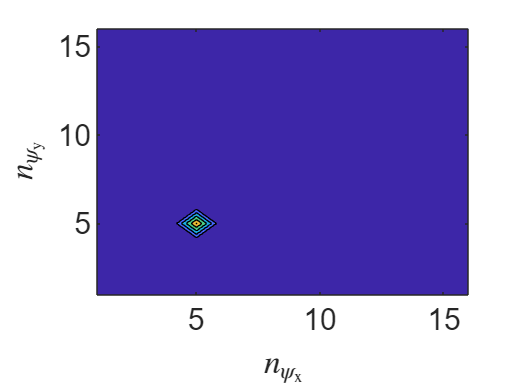

% %plotting the kernel
% figure;
% row_n_psy=2;
% plot(real(G(row_n_psy,:)),'LineWidth',2); grid on;
% xlabel('$n$','Interpreter','latex');
% ylabel('$\Re[\mathcal{F}_{n,n_\psi}]$','Interpreter','latex');
% yyaxis right
% plot(real(G_t(row_n_psy,:)),'LineWidth',2); grid on;
% ylabel('$\Re[\mathcal{F}_{n,n_\psi|t}]$','Interpreter','latex');
% legend_text=strcat('$n_\psi=',num2str(row_n_psy),'$');
% legend({legend_text},'Interpreter','latex');
% set(gca,'FontSize',font)
% saveas(gcf, './results/Fourier_real.fig');
% saveas(gcf, './results/Fourier_real.svg');
%plotting r_psi_x_y 
figure;
% transform a vector to the matrix with the reshape function
% the fliplr, flipud, and transpose operations are for the convenience of
% representing the x and y axes in the plot
R_psi_x_y = flipud(fliplr(reshape(r_psi_x_y, [N_x, N_y])))';
%[X,Y] = meshgrid(mod(2*(0:(N_x-1))'/N_x+1,2)-1,mod(2*(0:(N_y-1))'/N_y+1,2)-1);
% [X,Y] = meshgrid(linspace(-1,1,N_x),linspace(-1,1,N_y));
[X,Y] = meshgrid(linspace(1,N_x,N_x),linspace(1,N_y,N_y));
contourf(X,Y,abs(R_psi_x_y));
xlabel('$n_{\psi_\mathrm{x}}$','Interpreter','latex');
ylabel('$n_{\psi_\mathrm{y}}$','Interpreter','latex');
zlabel('$|\mathcal{F}_{n,n_\psi}$|','Interpreter','latex');
set(gca,'FontSize',font)


% figure;
% plot(real(a_psi_x));hold on
% plot(real(a_psi_x_y));

## References

[1] J. An et al., "Two-Dimensional Direction-of-Arrival Estimation Using Stacked Intelligent Metasurfaces," in IEEE Journal on Selected Areas in Communications, vol. 42, no. 10, pp. 2786-2802, Oct. 2024. doi: [10.1109/JSAC.2024.3414613](https://doi.org/10.1109/JSAC.2024.3414613)

[2] P. Heidenreich, A. M. Zoubir and M. Rubsamen, "Joint 2-D DOA Estimation and Phase Calibration for Uniform Rectangular Arrays," in IEEE Transactions on Signal Processing, vol. 60, no. 9, pp. 4683-4693, Sept. 2012, doi: [10.1109/TSP.2012.2203125](https://doi.org/10.1109/TSP.2012.2203125)